- Basic Image Processing

a) Load the image into workspace.

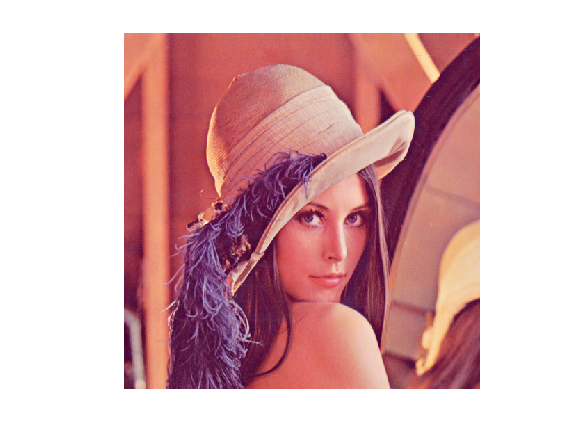

I=imread('lena.png');
imshow(I);

b) Determine the size of Image.

[Rows,Columns,Channels] = size(I);
fprintf('Rows = %d\nColumns = %d\nChannels = %d\n',Rows,Columns,Channels);

Rows = 512
Columns = 512
Channels = 3


c) Convert into Grayscale and find Max and Min value of Image.

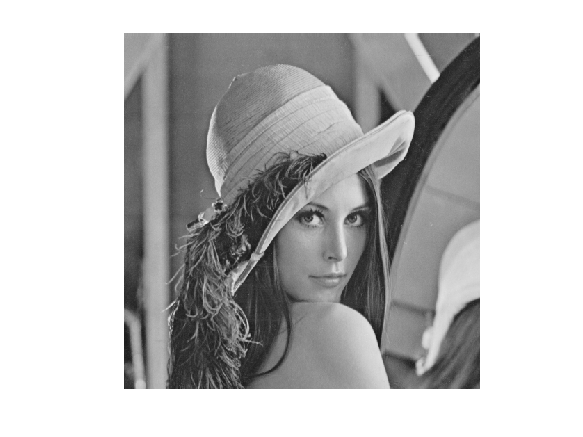

GreyImage=rgb2gray(I);
imshow(GreyImage)

MAX=max(GreyImage(:))

MAX = uint8
245

MIN=min(GreyImage(:))

MIN = uint8
25

d) Apply Gaussian smoothing filter.

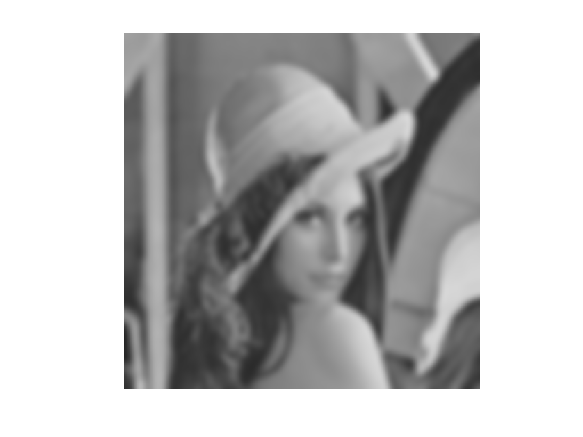

B=imgaussfilt(GreyImage,5);
imshow(B);

e) Display all the images 

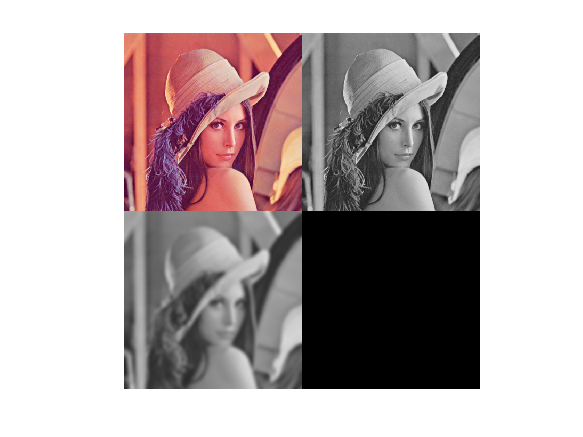

montage({I,GreyImage,B})